%% Testscript to test given labels from dataset
% First part
pic = imread("C:\Users\jonas\OneDrive\03_MA_Studium\04_Semester_2\34_Projekt\04_Daten\spray\spray_wet\images\6c78017a-1652343519909401092.png");
% imread("C:\Users\jonas\OneDrive\03_MA_Studium\04_Semester_2\34_Projekt\04_Daten\spray\spray_wet\images\6c78017a-1652343519909401092.png");
% imread("C:\Users\jonas\OneDrive\03_MA_Studium\04_Semester_2\34_Projekt\04_Daten\spray\spray_clear\images\0a429d27-1652966769163486864.png");

% read picture dimensions
szx = size(pic, 2)

szx = 407

szy = size(pic, 1)

szy = 256

% Second part
% read label fil; 
% assumption: <class> <coordinate x top left bounding box> <coordinate y top right bounding box> <length x bounding box> <length y bounding box>
txt = dlmread("C:\Users\jonas\OneDrive\03_MA_Studium\04_Semester_2\34_Projekt\04_Daten\spray\spray_wet\labels\6c78017a-1652343519909401092.txt");
% dlmread("C:\Users\jonas\OneDrive\03_MA_Studium\04_Semester_2\34_Projekt\04_Daten\spray\spray_wet\labels\");
% dlmread("C:\Users\jonas\OneDrive\03_MA_Studium\04_Semester_2\34_Projekt\04_Daten\spray\spray_clear\labels\0a429d27-1652966769163486864.txt");

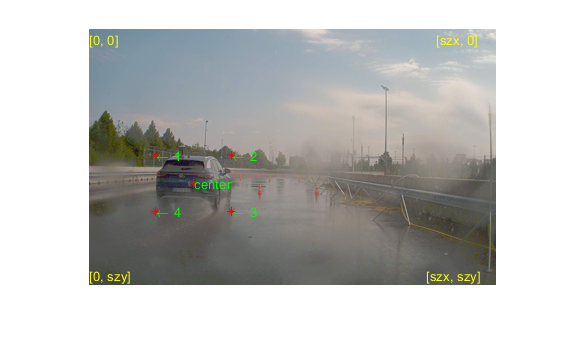

% Fourth
% assume origin is bottom right
figure();
imshow(pic);
nLabels = {'{1}'};
hold on
plot(szx*txt(2),              szy*txt(3),               '*', "color", 'red');
text(szx*txt(2),              szy*txt(3),               'center', 'Color', 'green');

plot(szx*txt(2) - (szx*txt(4))/2,            szy*txt(3) - (szy*txt(5))/2,  '*', "color", 'red');
text(szx*txt(2) - (szx*txt(4))/2,            szy*txt(3) - (szy*txt(5))/2,  '\leftarrow 1', 'Color', 'green');

plot(szx*txt(2) + (szx*txt(4))/2,            szy*txt(3) - (szy*txt(5))/2,  '*', "color", 'red');
text(szx*txt(2) + (szx*txt(4))/2,            szy*txt(3) - (szy*txt(5))/2,  '\leftarrow 2', 'Color', 'green');

plot(szx*txt(2) - (szx*txt(4))/2,            szy*txt(3) + (szy*txt(5))/2,  '*', "color", 'red');
text(szx*txt(2) - (szx*txt(4))/2,            szy*txt(3) + (szy*txt(5))/2,  '\leftarrow 4', 'Color', 'green');

plot(szx*txt(2) + (szx*txt(4))/2,            szy*txt(3) + (szy*txt(5))/2,  '*', "color", 'red');
text(szx*txt(2) + (szx*txt(4))/2,            szy*txt(3) + (szy*txt(5))/2,  '\leftarrow 3', 'Color', 'green');


% Koordinaten plotten
text(0, 10, '[0, 0]', 'Color', 'yellow');
text(szx-60, 10, '[szx, 0]', 'Color', 'yellow');
text(0, szy-10, '[0, szy]', 'Color', 'yellow');
text(szx-70, szy-10, '[szx, szy]', 'Color', 'yellow');